clear
clc
close all

%% Change directory
% Get the full path of the currently running script
if isdeployed
    % If the code is deployed, use the built-in method
    scriptFullPath = mfilename('fullpath');
else
    % If running in the MATLAB environment, use the editor API
    scriptFullPath = matlab.desktop.editor.getActiveFilename;
end

% Extract the directory part of the path
[scriptDir, ~, ~] = fileparts(scriptFullPath);

% Change the current directory to the script's directory
cd(scriptDir);

% Display the current directory to confirm the change
disp(['Current directory changed to: ', scriptDir]);

Current directory changed to: C:\Users\giaco\Git_Repositories\Semester_Thesis_1\Data\Battery


% Voltage vs SoC
data = readtable('Data/Battery/standard_battery.csv');
SoC = data.Var1;
voltage = data.Var2;

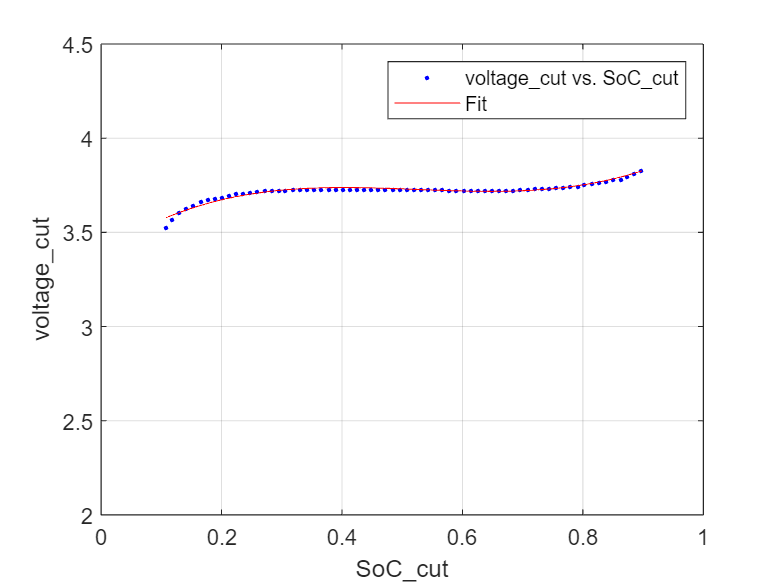

% SoC_smoothed = smooth(SoC, 15);
% voltage_smoothed = smooth(voltage, 15);

SoC_min = 0.1;
mask = SoC >= SoC_min & SoC <= 0.9;
SoC_cut = SoC(mask);
voltage_cut = voltage(mask);

[fitresult, gof] = safeFit(SoC_cut, voltage_cut);


coefficients = coeffvalues(fitresult);
disp('Fitted Coefficients of');

Fitted Coefficients of


disp(formula(fitresult));

p1*x^3 + p2*x^2 + p3*x + p4


disp(coefficients);

    2.7861   -4.3848    2.1768    3.3904



headers = {'a3', 'a2', 'a1', 'a0'};
coeff_table = array2table(coefficients, 'VariableNames', headers);
filename = 'battery_fitted_coefficients_3rd.csv'; % Change to .xlsx for Excel file
writetable(coeff_table, filename);

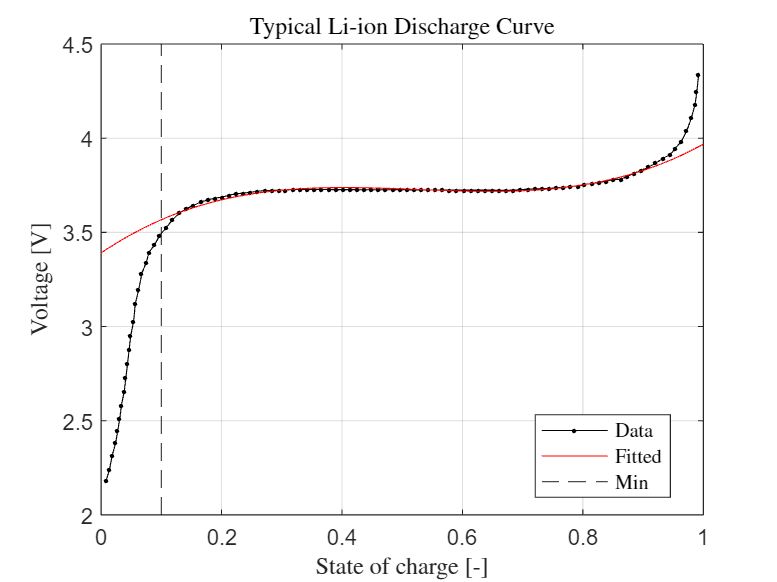

x = linspace(0,1,100);

figure
hold on
grid on
box on
plot(SoC, voltage, '.-k', 'DisplayName', 'Data')
plot(x, fitresult(x), 'r-', 'DisplayName', 'Fitted');
% plot(SoC_smoothed, voltage, '.-b', 'DisplayName', 'Smoothed')
xline(SoC_min, '--k', 'DisplayName', 'Min');
xlim([0 1])
ylim([2 4.5])
xlabel('State of charge [-]', 'Interpreter', 'latex')
ylabel('Voltage [V]', 'Interpreter', 'latex')
title('Typical Li-ion Discharge Curve', 'Interpreter', 'latex')
legend('Location','best', 'Interpreter', 'latex')